Lecture 10 MATLAB

% Example 1. Fourier Transform of rect[(t-0.5)/1] using fft and fftshift.
%
clear
clf;
fs = 100; ts = 1/fs; % fs = sampling frequency
t1 = 0; t2 = 5; tau = 1

tau = 1

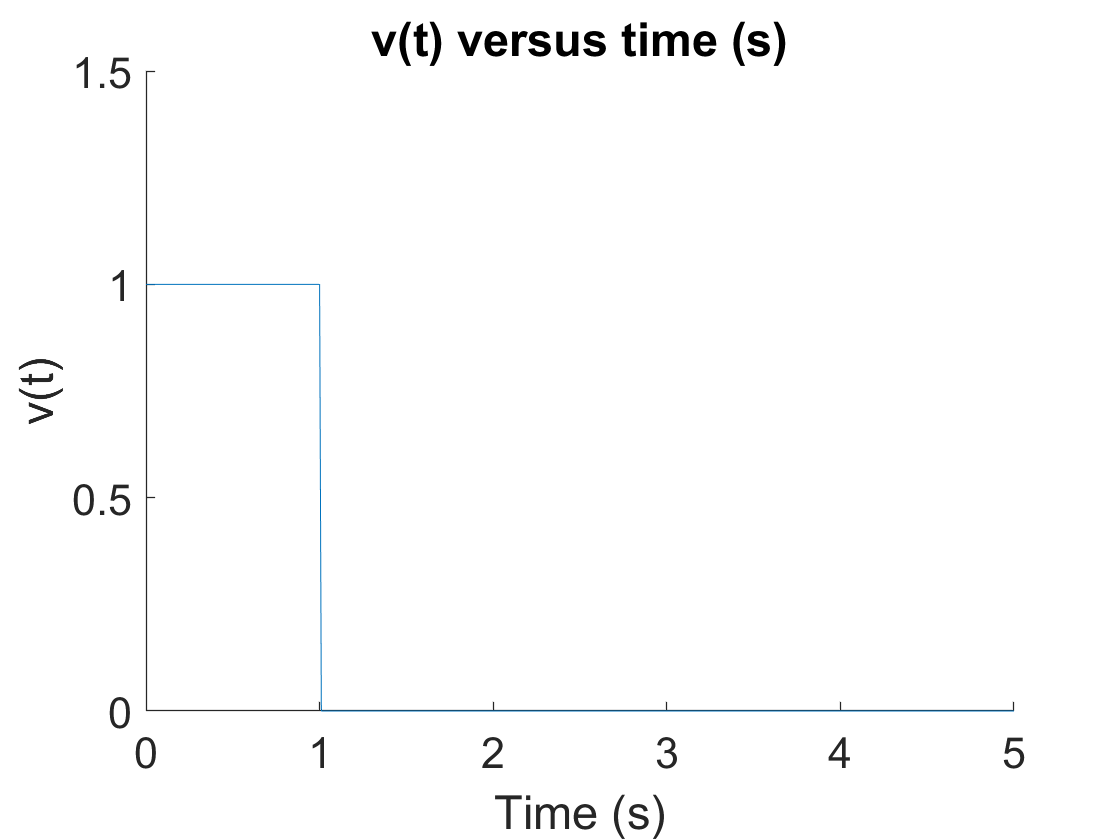

Av = 1; 
time = t1:ts:t2;
l = length(time);
% Generate v(n)
for n = 1:l
    if time(n) <= tau
        v(n) = Av;
    else v(n) = 0;
    end
    end
    plot(time,v)
     axis([0 5 0 1.5])
     xlabel('Time (s)')
     ylabel('v(t)')
 title('v(t) versus time (s)')
  set(gca, 'box','off');
  set(gca, 'FontSize', 16);

% hold on
%  stem(time,v)
% hold off

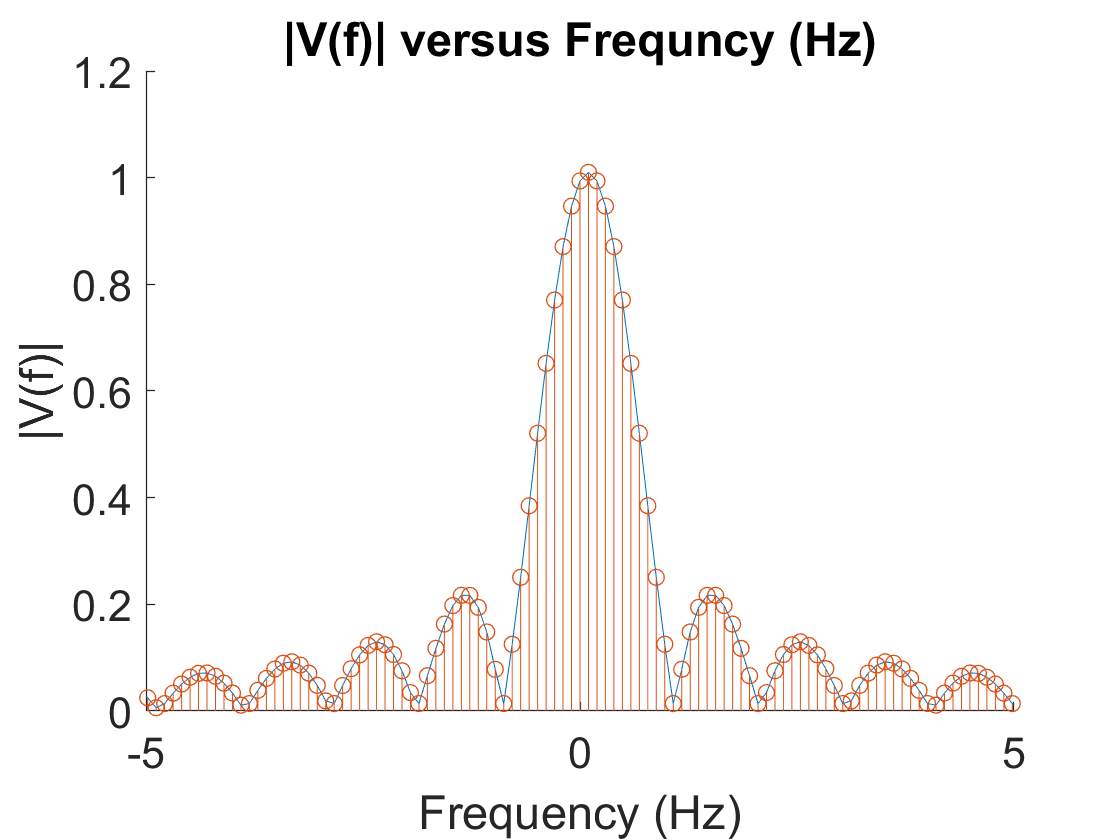


  % Find the Fourier Transform.
M = 2^10;
Vf = ts*fftshift(fft(v,M));
% Generate frequency axis
df = fs/M;
freq = -(fs/2 - df):df:fs/2;
plot(freq,abs(Vf));
axis([-5 5 0 1.2]) % Show only -5 to 5 Hz range. Full range: -50 to 50 Hz.
xlabel('Frequency (Hz)')
     ylabel('|V(f)|')
 title('|V(f)| versus Frequncy (Hz)')
  set(gca, 'box','off');
  set(gca, 'FontSize', 16);
hold on
stem(freq,abs(Vf)) % Show calculated |V(f)| samples
axis([-5 5 0 1.2])
hold off

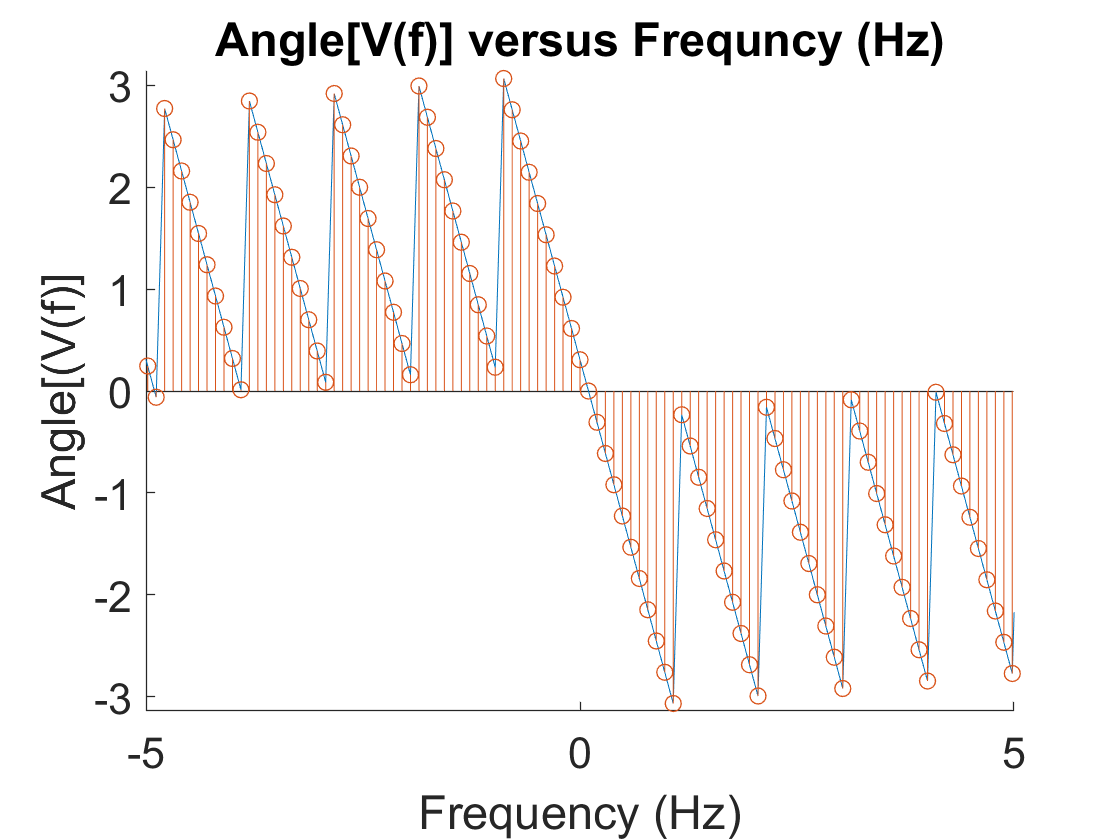

plot(freq,angle(Vf))
axis([-5 5 -pi pi])
hold on
stem(freq,angle(Vf))  % Show calculated Angle[V(f)] samples
axis([-5 5 -pi pi])
xlabel('Frequency (Hz)')
     ylabel('Angle[(V(f)]')
 title('Angle[V(f)] versus Frequncy (Hz)')
  set(gca, 'box','off');
  set(gca, 'FontSize', 16);
  hold off

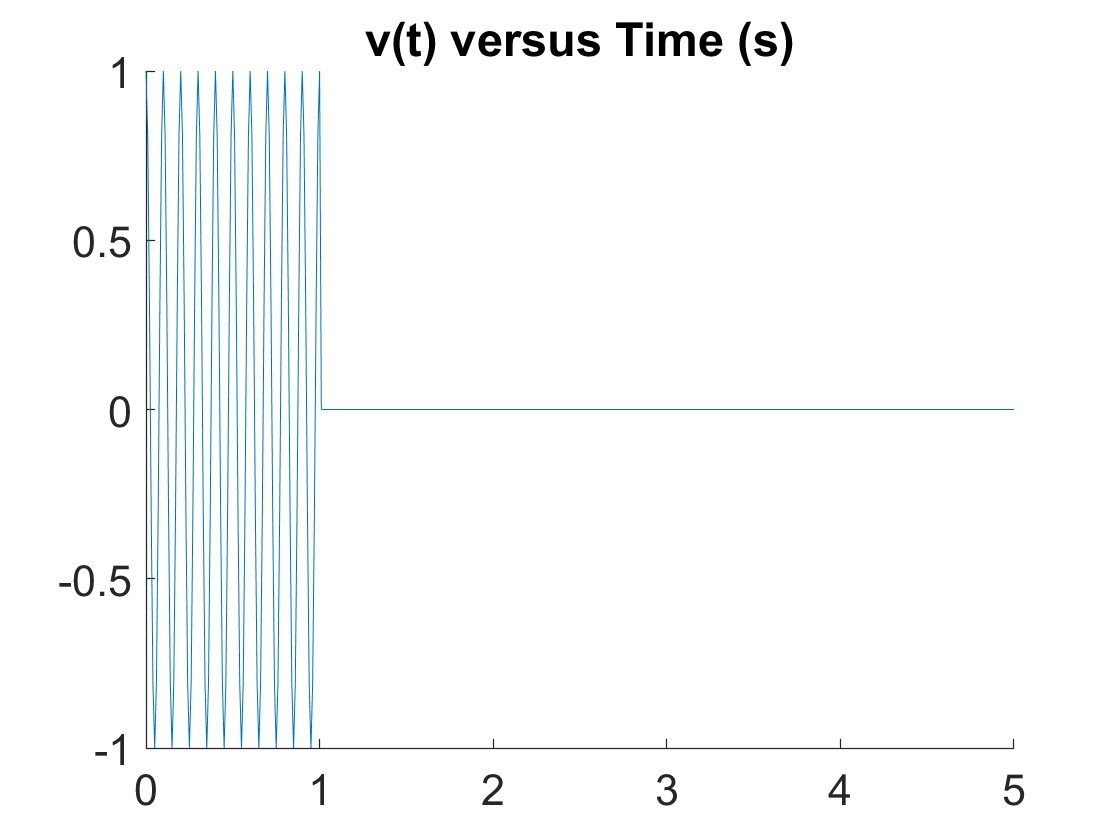


  % Example 2. Truncated cosine signal at 10 Hz.
% We can use some of the results from above.
f0 = 10;
vcos10 = v.*cos(2*pi*f0*time);
plot(time,vcos10);
title('v(t) versus Time (s)')
set(gca, 'box','off');
  set(gca, 'FontSize', 16);

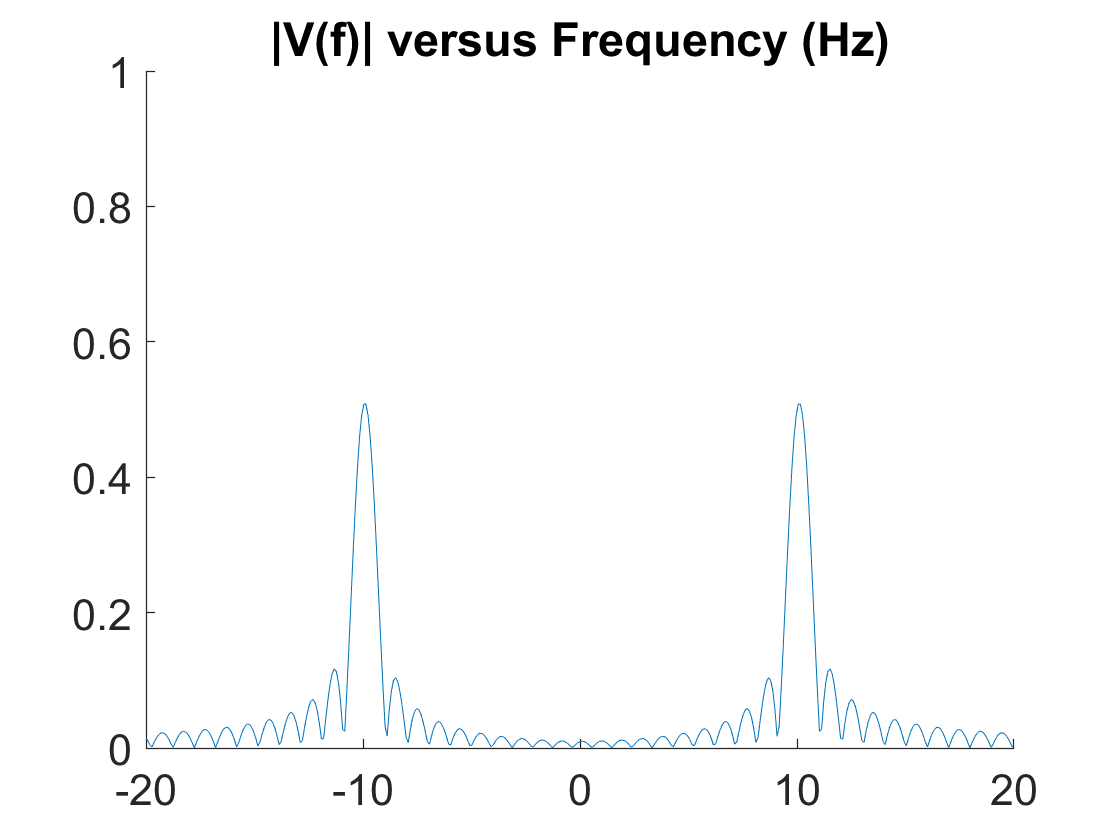

Vcos10f = ts*fftshift(fft(vcos10,M));
plot(freq,abs(Vcos10f));
axis([-20 20 0 1.0])
title('|V(f)| versus Frequency (Hz)')
  set(gca, 'box','off');
  set(gca, 'FontSize', 16);

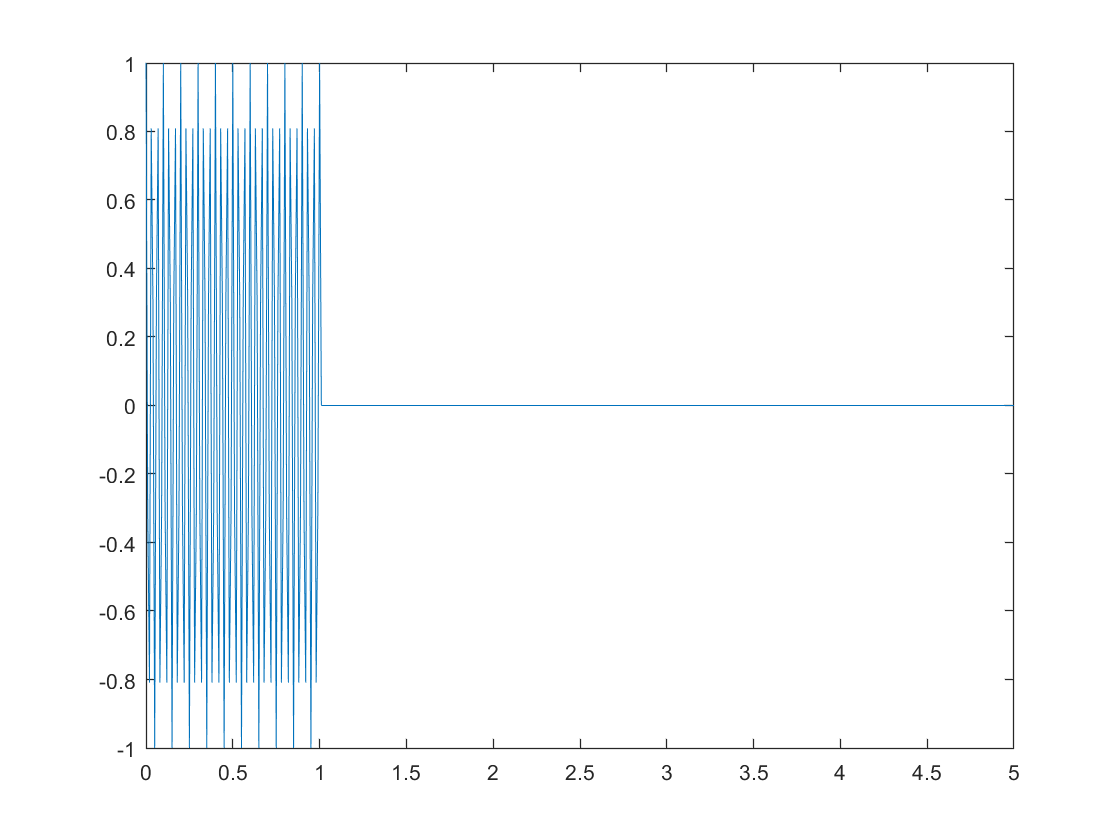

% Example 3.Demonstrate aliasing by finding the 
% Fourier transform of a 70 Hz signal sampled at 
% fs = 100 Hz.
f0 = 70;
vcos70 = v.*cos(2*pi*f0*time);
Vcos70f = ts*fftshift(fft(vcos70,M));
plot(time,vcos70);

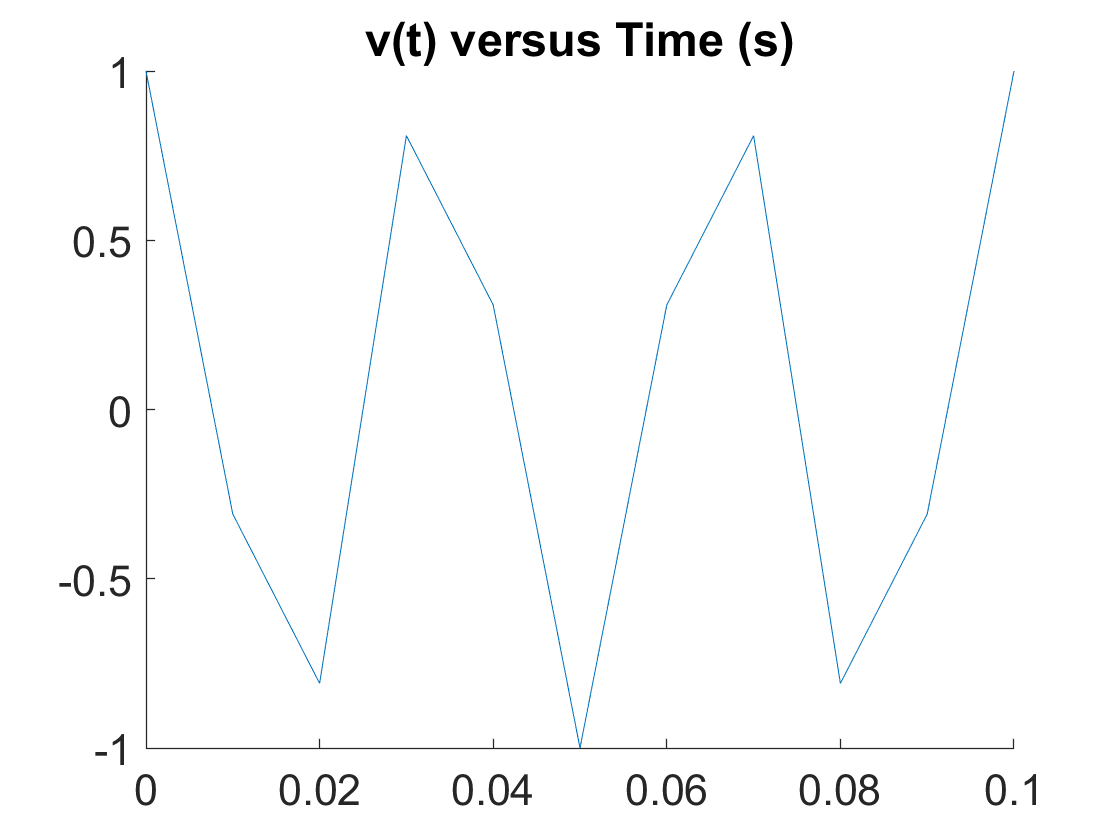

% Show result for 0.1 sec
plot(time,vcos70)  % Show result for 0.1 s  = 100 ms. We shall note only 3 cycles!
axis([0 0.1 -1 1])
title('v(t) versus Time (s)')
set(gca, 'box','off');
  set(gca, 'FontSize', 16);

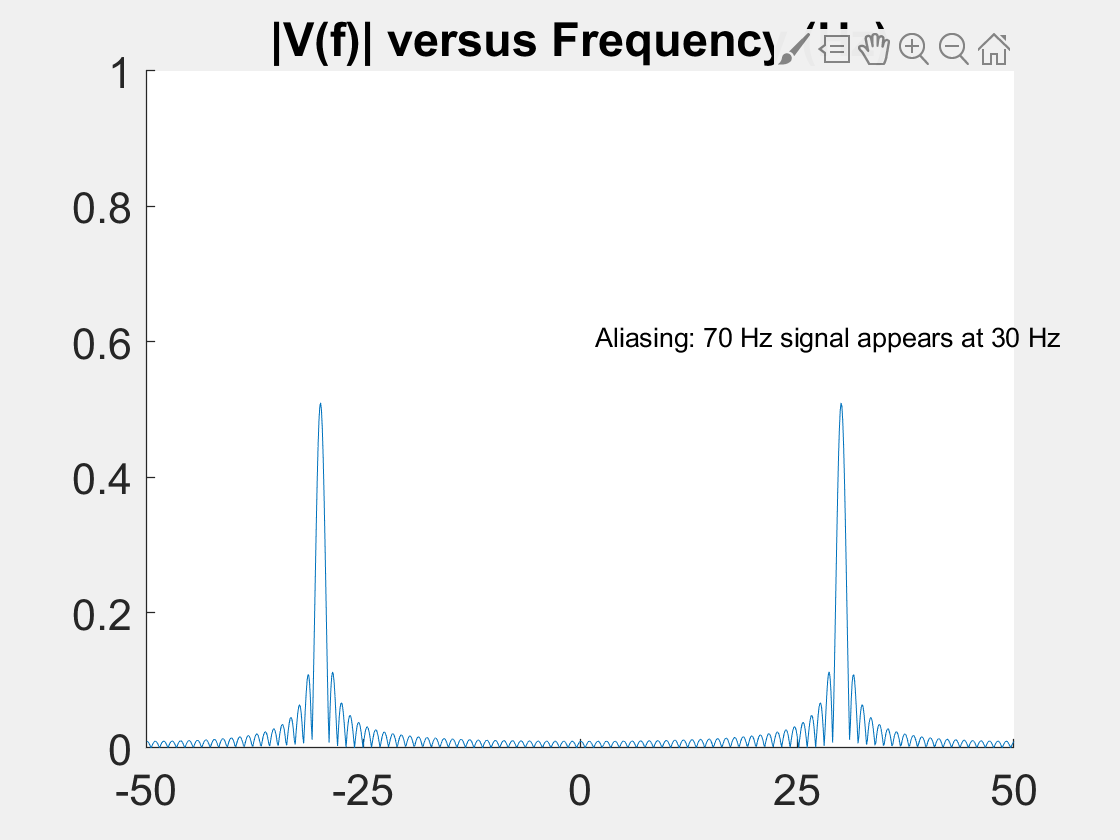

plot(freq,abs(Vcos70f));
axis([-50 50 0 1.0])
set(gca, 'XTick', [-50 -25 0 25 50])
title('|V(f)| versus Frequency (Hz)')
  set(gca, 'box','off');
  set(gca, 'FontSize', 16);
  gtext('Aliasing: 70 Hz signal appears at 30 Hz')